clear;
% PHYS 434
% LAB 2
% Jin Kyoung Lee

## Problem 1

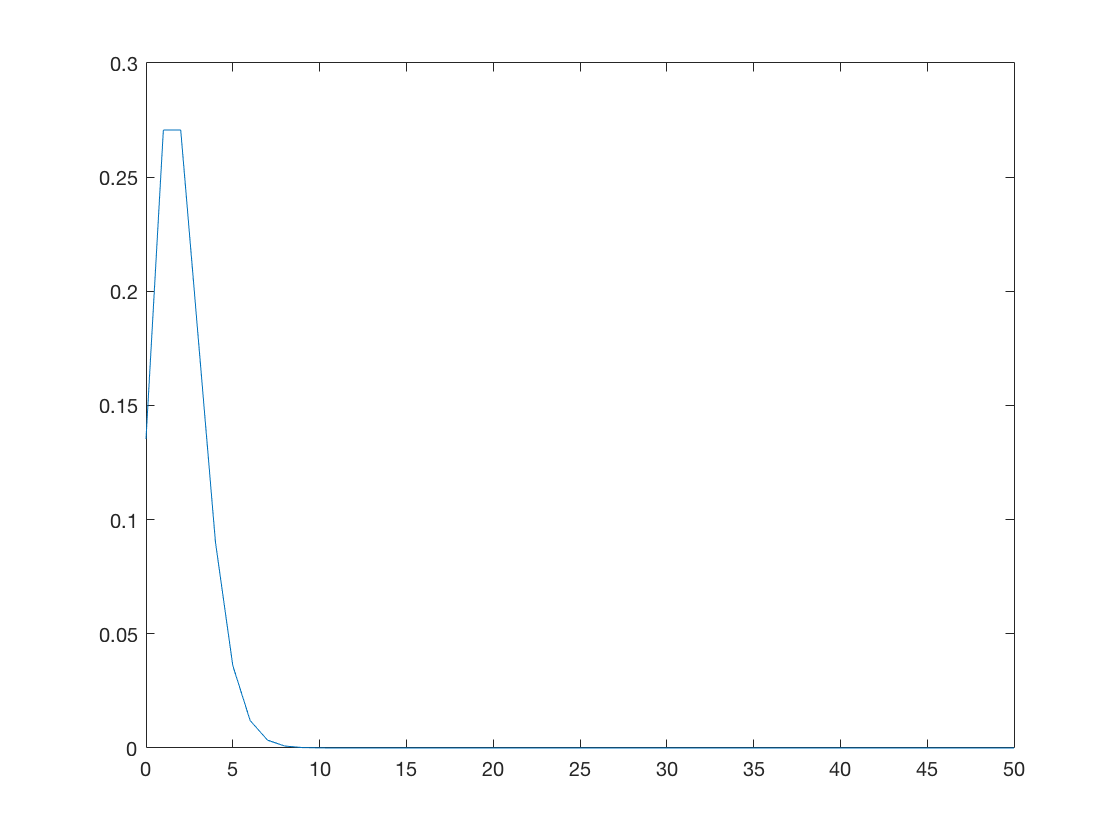

% Background of cosmic-rays follow a Poisson distribution
% In 1 day the average cosmic-ray background: X = lambda(λ) = 2
% The average number of gamma-rays emitted by the hypothetical source: Y = 4

%%% A) Cosmic-rays
% Day 1
background1 = 2;
x0 = linspace(0, 50, 51);
p1Day = poisspdf(x0, background1); % Create Poisson distribution with lambda = 2
plot(x0, p1Day);

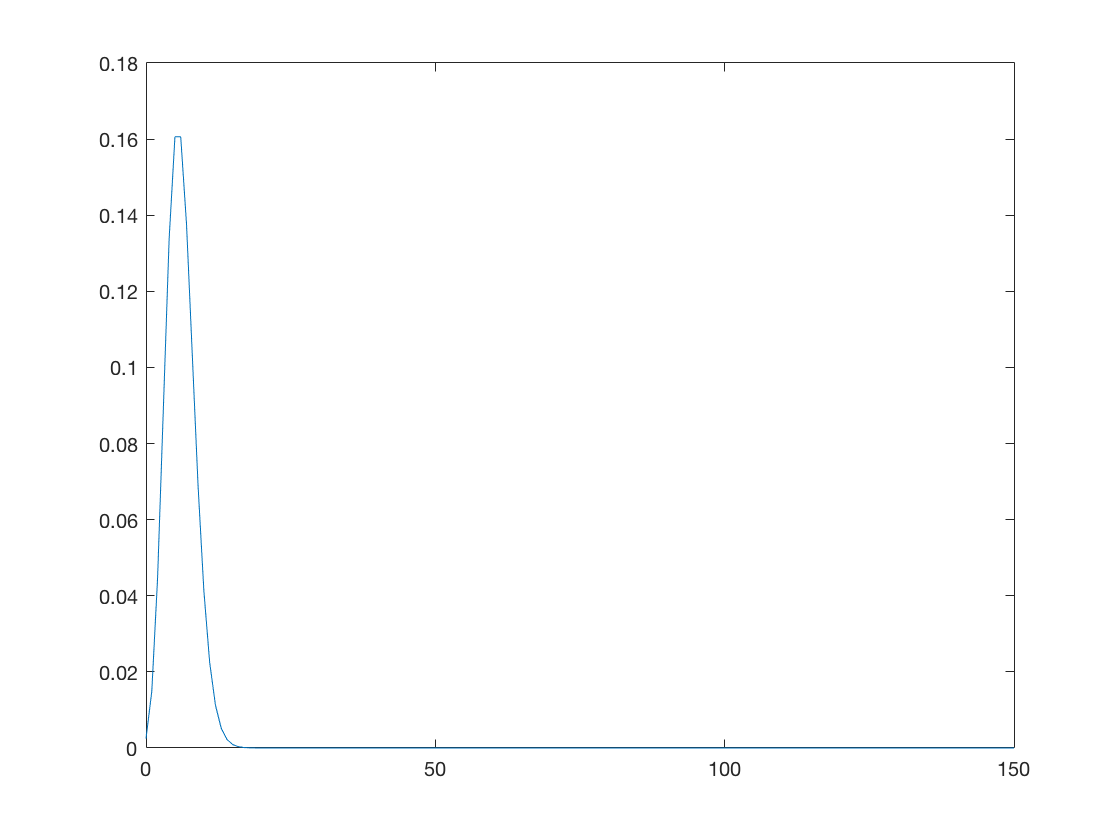

% Using convolution to get the probability distribution for more days
numOfDays = 3; % 3 days
p3Days = p1Day;
for i = 1:numOfDays-1
    p3Days = conv(p3Days, p1Day);
end
x = linspace(0, 50*numOfDays, 50*numOfDays+1);
plot(x, p3Days)

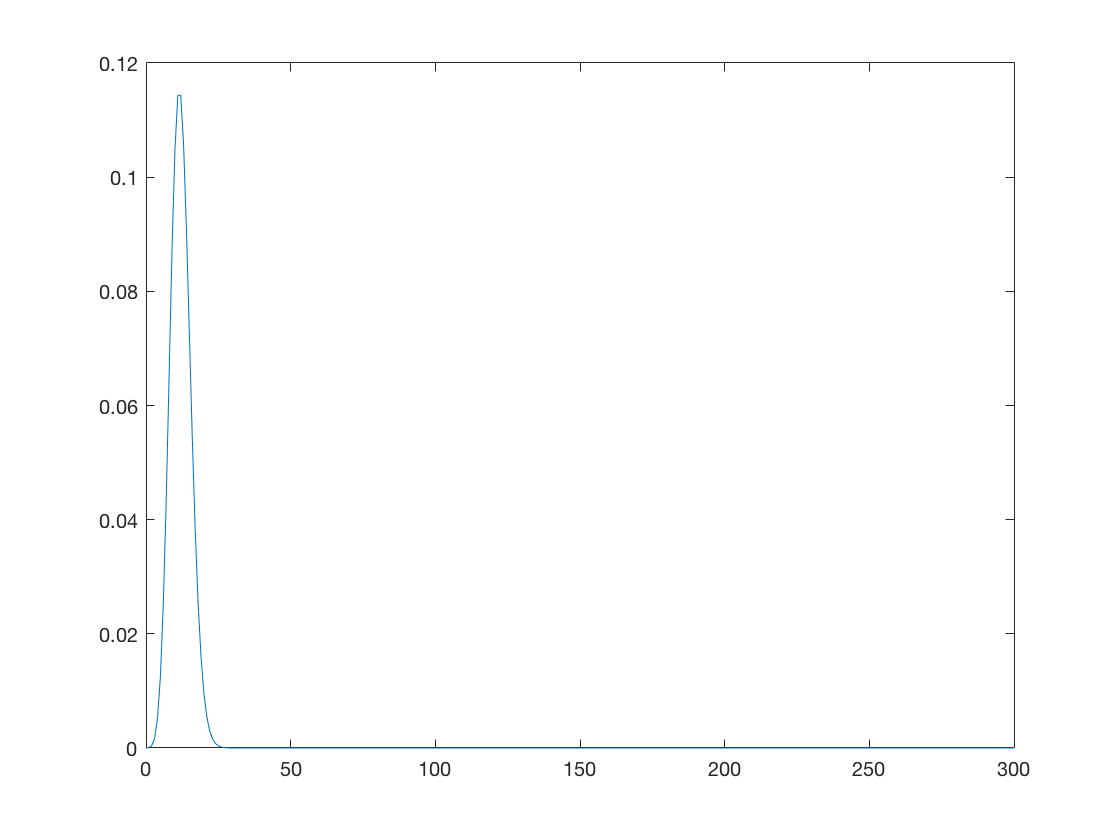

% By comparing the probability distribution for 1 day and for 3 days, we
% can see that as we integrate the probability distribution for more days,
% the background gets larger.

%%% B)
% Also using convolution to get the probability distributino after 5 days
numOfDays = 6; % Choosing the value greater than 5
p6Days = p1Day;
for i = 1:numOfDays-1
    p6Days = conv(p6Days, p1Day);
end
x = linspace(0, 50*numOfDays, 50*numOfDays+1);
plot(x, p6Days)

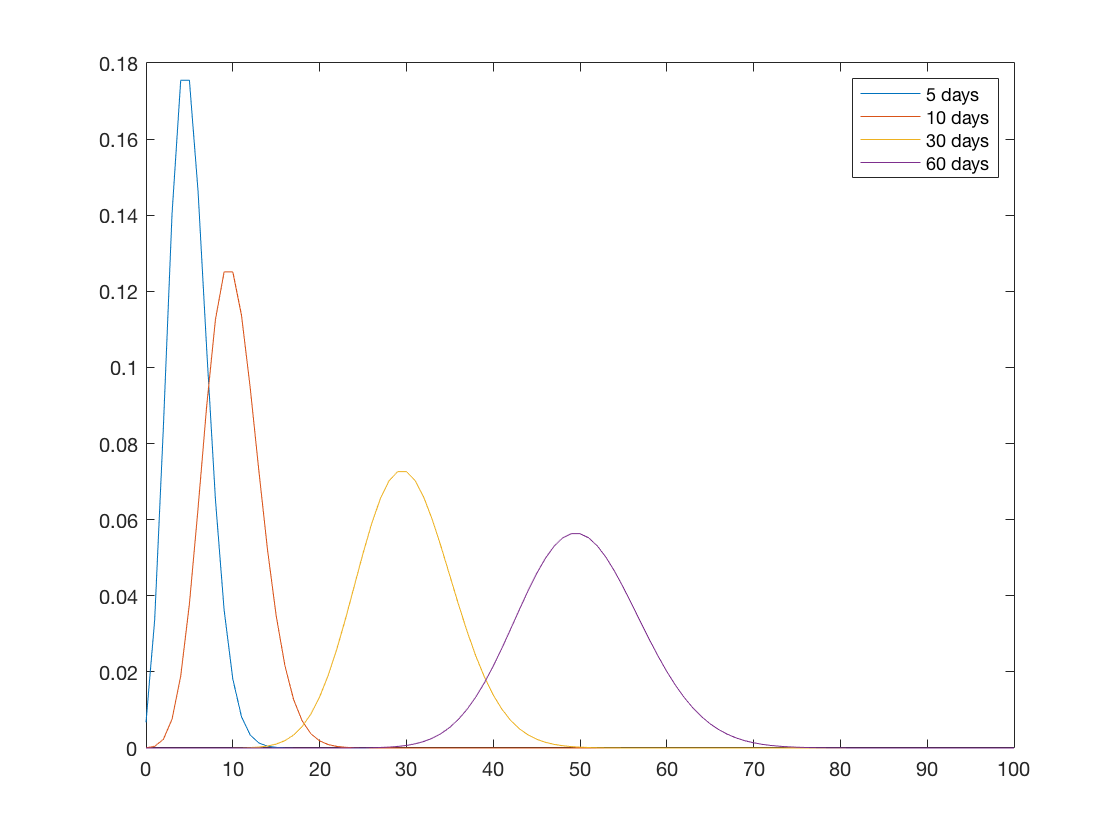

% From part A), we found that adding probability distribution for 3 days
% was still a Poisson distribution. Also, here in part B), by using
% the same method that of part A), it is proved that after 5 days,the
% summed probability disdtribution is still A Poisson distribution.
% Since we didn't sum up enough trials, the distribution is still Poisson
% distribution. However, if we sum up more trials, then, the distribution
% will converge to a Gaussian distribution.

%%% C)
x1 = linspace(0,100,101);
% Averaging 5 days
p5Days = poisspdf(x1, 5);

% Averaging 10 days
p10Days = poisspdf(x1, 10);

% Averaging 30 days
p30Days = poisspdf(x1, 30);

% Averaging 50 days
p50Days = poisspdf(x1,50);

% Plotting distributions to compare the shape
plot(x1,p5Days)
hold on
plot(x1,p10Days)
plot(x1,p30Days)
plot(x1,p50Days)

legend('5 days','10 days','30 days','60 days')
hold off

% As the average days increases, the distribution becomes normal
% distribution. According to central limit theorem, if there is more trials
% then a distribution will converge to Gaussian distribution. Therefore, as
% we average more days, the distribution becomes normal distribution.

%%% D) Number of days: N = 3
% Gamma rays from the source: Y*N = 4 * 3 = 12
poissCosRays = makedist("Poisson",'lambda',background1);
pGammaRays = 1 - cdf(poissCosRays, 12)

pGammaRays = 2.0735e-07

sigmaGammaRays = icdf('Normal',1-pGammaRays,0,1)

sigmaGammaRays = 5.0621

## Problem 2

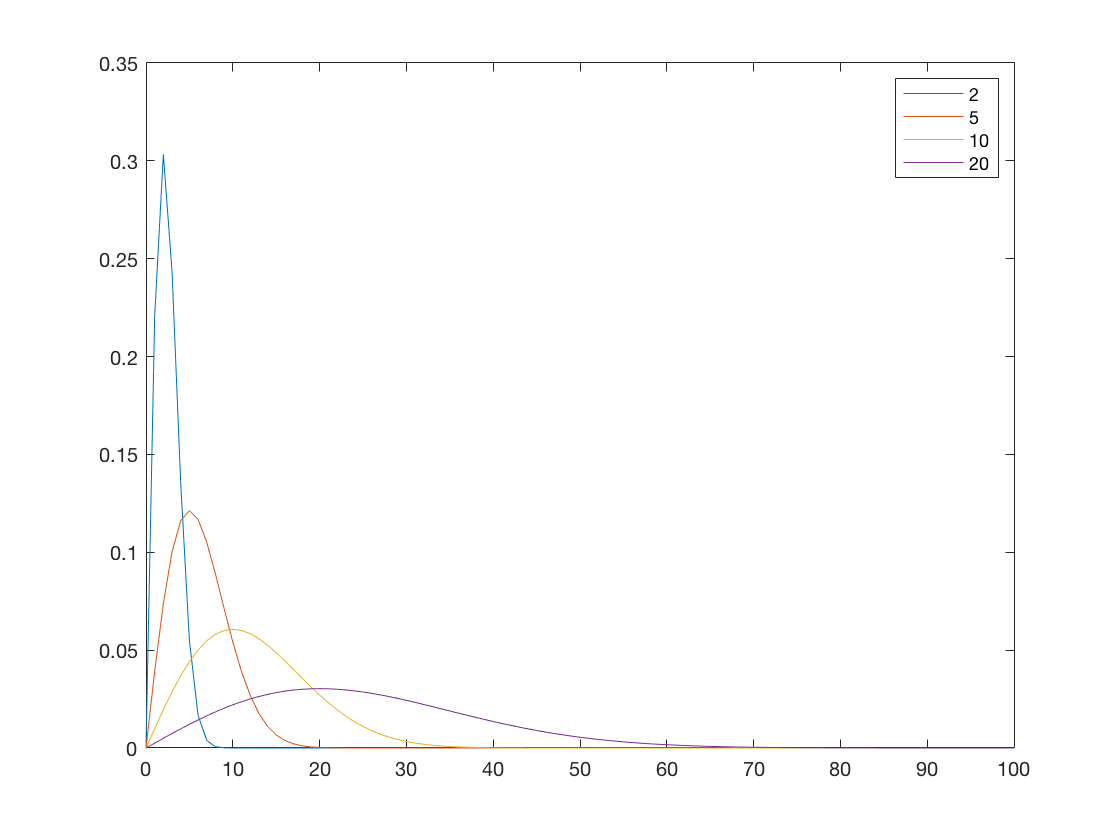

x2 = linspace(0,100,101);
% parameter = 2
r2 = raylpdf(x2,2);
% parameter = 5
r5 = raylpdf(x2,5);
% parameter = 10
r10 = raylpdf(x2,10);
% parameter = 20
r20 = raylpdf(x2,20);

% Plotting
plot(x2,r2)
hold on
plot(x2,r5)
plot(x2,r10)
plot(x2,r20)

legend('2','5','10','20')
hold off

% Yes, it approaches a Gaussian distribution as the parameter gets larger.
% This happenes when the parameter exceeds 5.

## Problem 3

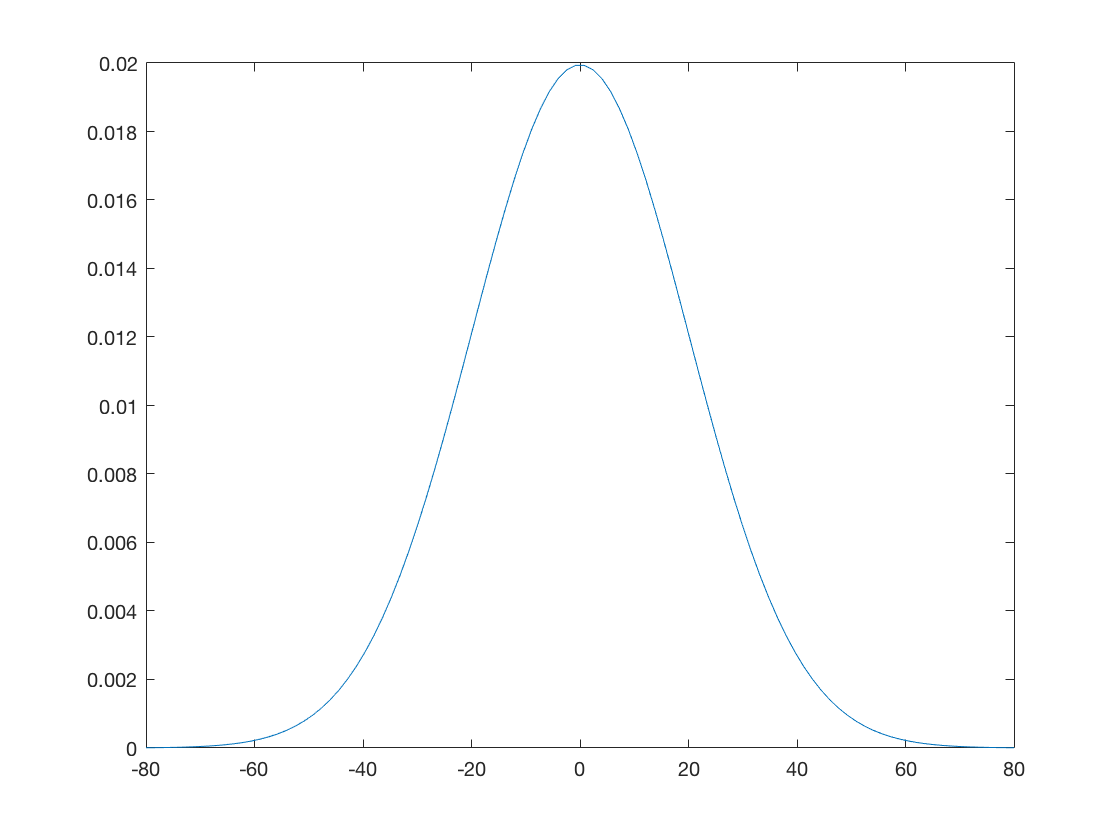

%%% Version 1
%%% A)
% Width of the background Gaussian distribution: x = 20
% Signal of strength: Y = 87.65
% Mean = 0
% Standard deviation = 20
% What is the probability of finding a signal of strength 87.65 from the
% background Gaussian distribution with the width of 20?
x3 = linspace(-80,80,100);
normCCD1 = makedist("Normal","mu",0,"sigma",20);
plot(x3,pdf(normCCD1,x3))

pCCD1 = 1 - cdf(normCCD1,87.65)

pCCD1 = 5.8663e-06

sigmaCCD1= icdf('Normal',1-pCCD1,0,1)

sigmaCCD1 = 4.3825

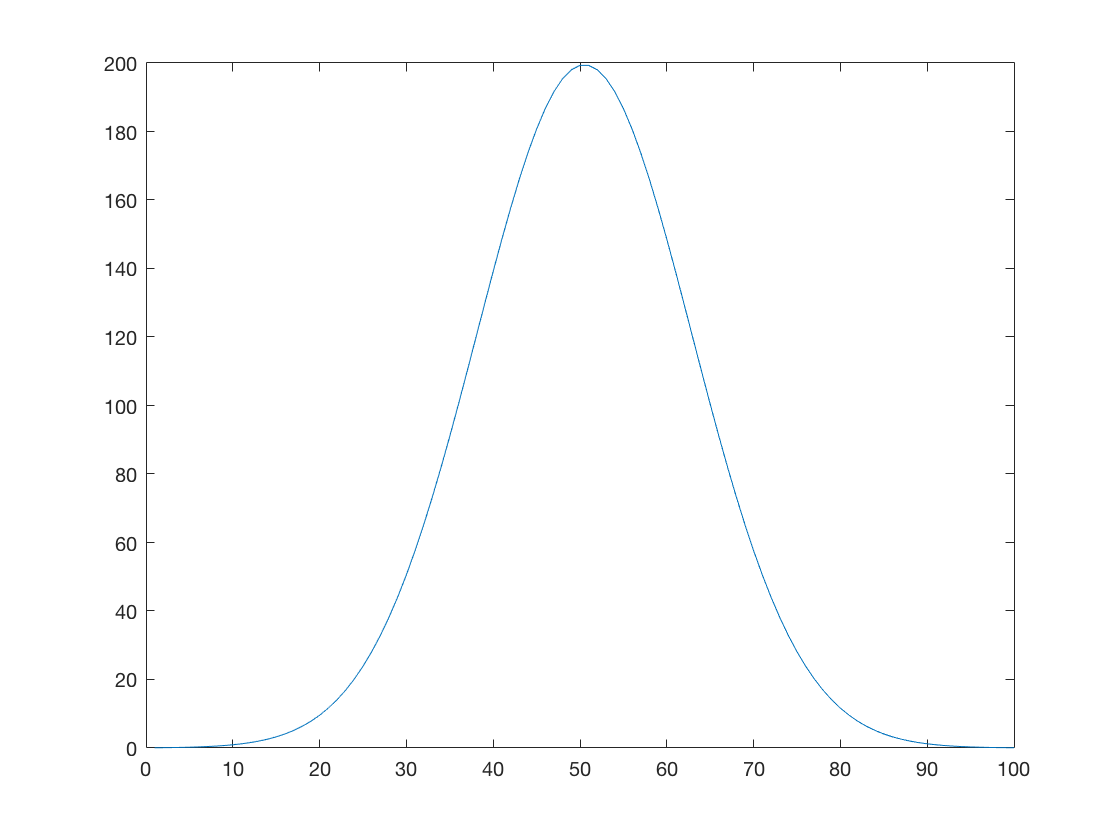

% To detect a signal of strength 87.65 has sigma value of 4.3825, which is
% less than 5 sigma. Therefore, we cannot claim a discovery.

%%% Version 2
%%% B)
% The probability idstribution when looking for a signal in 10k pixels, it
% will still be Gaussian distribution.

%%% C)
pixel = 10000;
normCCD2 = pdf(normCCD1,x3)*pixel;
plot(normCCD2)

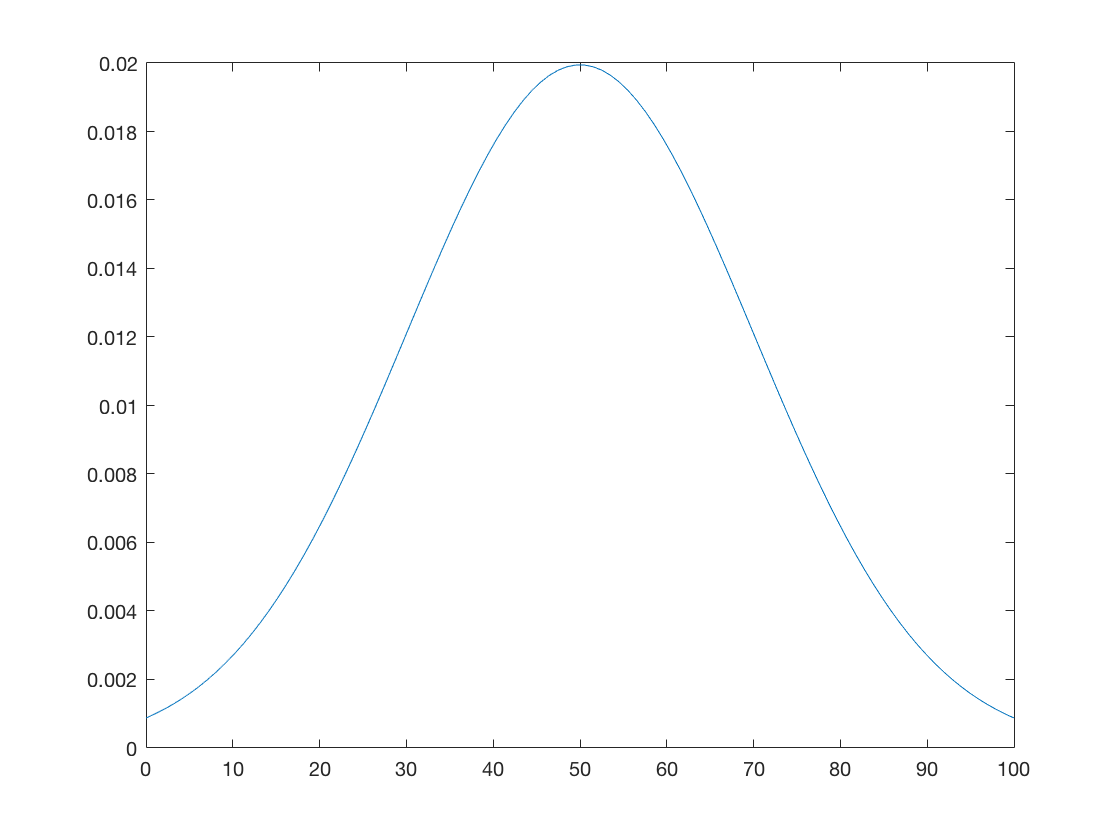

nCCD2 = makedist("Normal","mu",50,"sigma",20);
x4 = linspace(0,100,100);
plot(x4,pdf(nCCD2,x4))

pCCD2 = 1 - cdf(nCCD2,87.65)

pCCD2 = 0.0299

sigmaCCD2= icdf('Normal',1-pCCD2,0,1)

sigmaCCD2 = 1.8825

## Problem 4

%%% A) What is the strength of a signal that produces 5 sigma?
% sigmaV1 = norminv([0.0000003,0.9999997])
pCCD1 = 1 - cdf(normCCD1,100.65)

pCCD1 = 2.4206e-07

sigmaV1CCD = icdf('Normal',1-pCCD1,0,1)

sigmaV1CCD = 5.0325

% A strength of 100.65 signal is required to get 5 sigma.

%%% B)
pCCD2 = 1 - cdf(nCCD2,150.65)

pCCD2 = 2.4206e-07

sigmaCCD2= icdf('Normal',1-pCCD2,0,1)

sigmaCCD2 = 5.0325

% A strength of 150.65 signal is required to get 5 sigma.

%%% C) The signal must be +50 brighter, if we have a trials factor of 10k.